# PHYS 361 Lab 3: If statements, loops, and basic plots

## Group Warm Up: 

The Taylor series for expansion for cos(x) is:


$$cos(x) = 1-\frac{x^2}{2!}-+\frac{x^4}{4!}-\frac{x^6}{6!}+...=\sum^\infty_{n=0}\frac{(-1)^n}{(2n)!}x^{2n}$$


where x is in radians. Write a `while` loop that determines $cos(35^\circ)$.  For each pass of the loop, calculate both the series sum and the estimated error:


$$E=\left|\frac{S_n-S_{n-1}}{S_{n-1}}\right|$$


where $S_n$ is the n-th term of the series. Stop adding the terms when $E \le 0.000001$.

% initialize the value, index n, and x in radians
value = 1;
n = 0;
x = deg2rad(35);

% initialize term variables
next_term = 1;
last_term = value;

% define the error end condition
accept_err = 1e-6;

% define an initial error
est_err = accept_err;

% start calculating terms
while est_err >= accept_err
	% iterate n
	n = n + 1;

	% calculate and add to value
	next_term = (-1).^n * x.^(2*n) / factorial(2*n);

	% add the term and recalculate error
	value = value + next_term;
	est_err = abs( (next_term - last_term) / last_term) - 1;

	% save the next term as last term
	last_term = next_term;
end

% print the value and est err
fprintf("value= %f, estimated error= %f, n= %d", value, est_err, n);

value= 0.819152, estimated error= 0.000000, n= 81

## Problem 1: Make a unit conversion live script

Write a live script that converts pressure units. At the top of the Pa and psi, or atm and the program will give the equivalent value in another unit system specified by the user.  The top of the program should specify (1) the pressure, (2) the orginal unit (either Pa, psi, or atm), and (3) the desired unit (again either Pa, psi, or atm). I have provided two options for getting input from the user to get you started.  You can use the built in function `strcmp` to compare to string variables. You do not need to do a fancy formatted output unless you want to.

Use the program to:

(a) Convert 70 psi to Pa

(b) Convert 800 Pa to psi

(c) Convert 1 atm to psi

% get initial values from user in the command window (option 1)
% press = input('Input the pressure you want to convert: ');
% unitin = input('Input the original unit (psi, Pa, or atm):' , 's');
% unitout = input('Input the desired unit (psi, Pa, or atm):' , 's');

% get initial values from user using Live Script features(option 2)
press = 1;
unitin = 1;
unitout = 3;

% unit conversion values 
% conversion ratio to go from atm to psi, etc.
atm2psi = 14.6959;
atm2pa = 101325;
pa2psi = 1.45038e-4;
pa2atm = 1/atm2pa;
psi2atm = 1/atm2psi;
psi2pa = 1/pa2psi;

% define unit strings for printing
u_strs = ["Pa", "psi", "atm"];

% define a transformation matrix
pressure_transform = [1, psi2pa, atm2pa; pa2psi, 1, atm2psi; pa2atm, psi2atm, 1];

% define the user input matrix
user_in = zeros(3,1);
user_in(unitin) = press;

% apply the transform and select answer
user_out = pressure_transform * user_in;

% print the user expected answer
fprintf("%f %s = %f %s\n", press, u_strs(unitin), user_out(unitout), u_strs(unitout))

1.000000 Pa = 0.000010 atm


## Problem 2: Loop Practice

A person in retirement deposits $300,000 in a saving account that pays 5% interest every year. The person plans to withdraw $25,000 the first year. After the first year, they plan to increase the amount withdrawn by the inflation rate. For example, if the inflation rate is 3% they will withdraw $25,750 the second year.  I have added pseudo code in comments to get you started.

a) Determine how many years the money in the account will last using a while loop assuming a constant yearly inflation rate of 2%. Protect your while loop by putting in a counter to prevent it from running indefinitely if you make a mistake. [The correct answer is 16 years.]

b) Determine how many years the money in the account will last using the current inflation rate. Look it up!

% set initial amount of money [$]
money = 300000;
% set initial withdraw amount [$]
withdraw = 25000;
% set the year index
year = 0;
% set the inflation rate [%]
inflation_rate = 2;
% set the interest rate [%]
interest_rate = 5;

% loop until no money is left
while money >= 0
	% calculate the withdraw amount for the year
	% do so only if the year is not the first year
	if year > 0
		withdraw = withdraw * (1 + (inflation_rate / 100));
	end

	% calculate interest payout
	interest_payout = money * (interest_rate/100);

	% change account balance
	money = money + interest_payout - withdraw;  
    
    % iterate year
	year = year + 1;

	% while protection
	if year >= 1000
		break;
	end
end

% print the number of years the account lasted
fprintf("The account lasted for %d years.", year);

The account lasted for 16 years.

## Problem 3: Plotting Functions

According to special relativity the mass *m, * the momentum *p*, and the kinetic energy K of a particle moving with speed *v* are giving in terms of the rest mass $m_0$ and the speed of light* c* by the equations

             $m=\frac{m_0 }{\sqrt{1-\beta^2 }}$;         $p=\frac{m_0 v}{\sqrt{1-\beta^2 }}$ ;                $K=\frac{m_0 c^2 }{\sqrt{1-\beta^2 }}-m_0 c^2$.

where $\beta =\frac{v}{c}\ldotp$  Using [anonymous function](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) and `fplot, `make graphs of $\frac{m}{m_o }$,$\frac{p}{m_0 c}$, and $\frac{K}{m_0 c^2 }$ versus $\beta$ . Choose interesting values to examine and briefly describe the results. You must include labels on the axes that are generated by code for full points.

I'm not too sure where this warning comes from but I think anonymous functions arent designed for vector input so MATLAB complains.

% define the rest mass [kg]
m0 = 1;

% define the speed of light c [m/s]
c = 3e8;

% define the functions
rel_m = @(beta) m0 / sqrt(1 - beta.^2);
rel_p = @(beta) rel_m(beta) * (beta * c) / sqrt(1 - beta.^2);
rel_k = @(beta) (rel_m(beta) * c.^2 / sqrt(1 - beta.^2)) - (rel_m(beta) * c.^2);

% define the functions to graph
rel_m_ratio = @(beta) rel_m(beta) / m0;
rel_p_ratio = @(beta) rel_p(beta) / (m0 * c);
rel_k_ratio = @(beta) rel_k(beta) / (m0 * c.^2);

% generate plot of rel_m
fplot(rel_m_ratio, [0, 1], "-k")

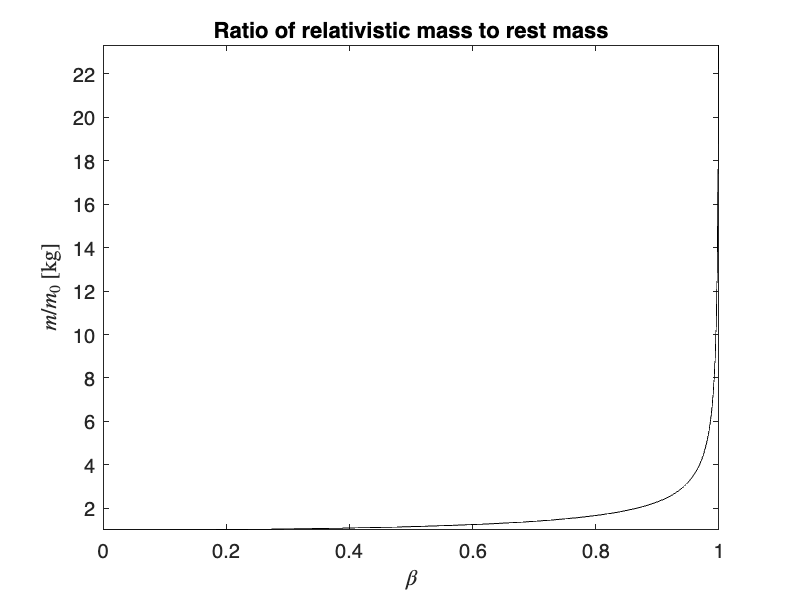

xlabel("$\beta$", Interpreter="latex")
ylabel("$m / m_0$ [kg]", Interpreter="latex")
title("Ratio of relativistic mass to rest mass")


% generate plot of rel_p
fplot(rel_p_ratio, [0, 1], "-k")

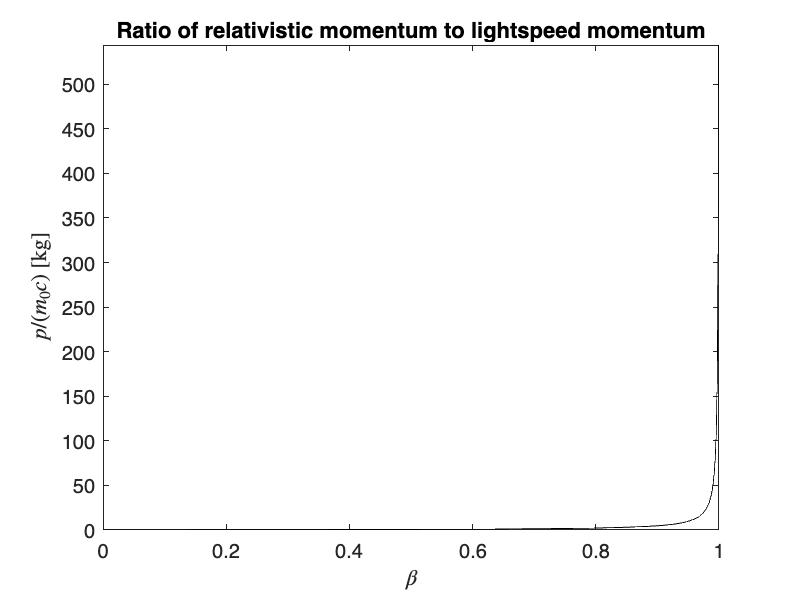

xlabel("$\beta$", Interpreter="latex")
ylabel("$p / (m_0 c)$ [kg]", Interpreter="latex")
title("Ratio of relativistic momentum to lightspeed momentum")


% generate plot of rel_k
fplot(rel_p_ratio, [0, 1], "-k")

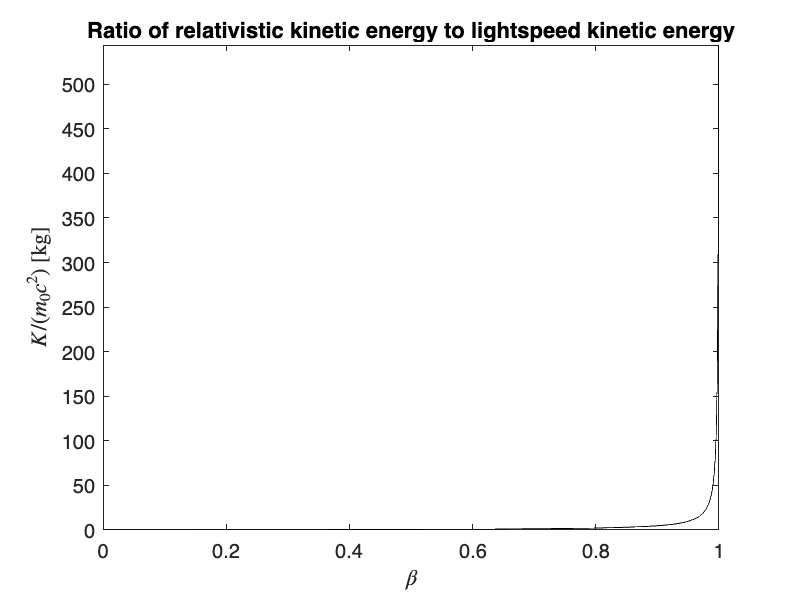

xlabel("$\beta$", Interpreter="latex")
ylabel("$K / (m_0 c^2)$ [kg]", Interpreter="latex")
title("Ratio of relativistic kinetic energy to lightspeed kinetic energy")

## Problem 4: Random Walk 

Random walks are useful for simulating the diffusion of particles in a liquid or gas, the movement of bacteria in a solution, or even the escape of photons from the center of the Sun.  

First we will program a random walk in one-dimension: 

a) Write a program that calculates the number of steps required for a particle to move a distance of $\pm 10$ units. The position $x$ of a particle will be computed by:


$$x_{j+1} =x_j +s$$


where $s$ is a random number between -1 and 1. The initial position of the particle will be $x=0\ldotp$  (**Hint**: Use `rand(1)`, which generates a random number between 0 and 1, to generate a random number between -1 and 1. Google "concatenate array MATLAB" if you aren't sure how to add values to the end of an array.)   

b) Copy your code from part (a) and past it below. Change that code so that it runs through a loop to calculate the number of steps needed to move a length *L* that varies from 5 to 100 units in increments of 5  (`L=10:5:100)`. The initial posiiton of the particle will always start at 0.

The code should store the number of steps needed to travel each length, L. This can be done by initializing an empty array (e.g. steps_per_L=[]) at the top of the code and then concatenating new values the the end of the array everytime you run the code for a new length, *L*.

Finally, make a plot that shows the number of steps needed to move each value of L.  (e.g. L vs. number of steps).

clear; %Clear all variables in the workspace

%Initialize an array to number of steps for each L distance
stepsperL=[]; 


c) **Extra Credit:** Now let's do this calculation in two-dimensions.  Instead of having the object move a random distance, the particle will always move 1 unit but the direction of motion will be random.  The following code will give you a random number between 0 and $2\pi$. Try running it a few times to confirm.

theta=rand(1)*2*pi

Once you have selected a random angle you can determine the change in position of a particle in the x and y directions using the following equations:

                                                                  
$$\begin{array}{l}
\delta \;x=\left(1\right)\cos \left(\theta \right)\\
\delta \;y=\left(1\right)\sin \left(\theta \right)
\end{array}$$


Write a program that determines how many steps a particle needs to move a distance of 100 units away from the origin, assuming the particle starts at (x,y)=(0,0). Save the values of x and y for each step and make a plot showing the particle's 2D path through space.

clear; %Clear all variables in the workspace
